Simulations.DefaultValues;

%{
Vv = 30/1000;
CL = 20/1000/3600;
time_values_needed = [1 3 12 24 48]*3600;

immunoreactivity = 0.69; %doesn't matter for fitting part
tumorload = 4.755e-7; %aka R0, the initial [receptors] in mol/L
perTV = 0;
perNB = 0.01;
kAR = 1.846e4; %+/-.006e4, which is specifically for m8H9 with 4Ig-B7-H3
k_AR = 1.650e-4;%+/-.002e-4, which is specifically for m8H9 with 4Ig-B7-H3
V = 0.140; %doesn't matter for fitting part
Vs = V - Vv;
n = 1;
MM = 10*2.4908102999999997e-19 * 6.022e23; %1499965.96266
cI0 = 49/10; %mCi/mg, Ci/g, or 185MBq/mg
%}
  
%Use an R0 that is 10x greater (and state so in the figure caption)
%so that AUC[C_IA] and AUC[C_IAR] are more easily plotted in one figure
tumorload = 1.193674951486256e+13 / (6.022e23) *1000;

activities = sort([0 0.25 0.5 1 2:1:70]);
ys = zeros(4,length(activities));
ys_adj = zeros(4,length(activities));
for it = 1:length(activities)
    activityAdmin = activities(it);
    defined_params = [immunoreactivity, tumorload, perTV, perNB, ...
        kAR, k_AR, V, n, MM, cI0, t_half];
    [t, cIobs, AUC_cIAR, AUC_cIA] = solveModel(activityAdmin,...
        Vv, CL, time_values_needed,defined_params);
    therap_ratio = [AUC_cIAR    AUC_cIA...
        (AUC_cIAR)/AUC_cIA (AUC_cIAR)/AUC_cIA*AUC_cIAR];
    %title(['Act. ' num2str(activityAdmin) ', AUC: ' num2str(AUC_cIA)]);
    
    ys(:,it) = therap_ratio;
end

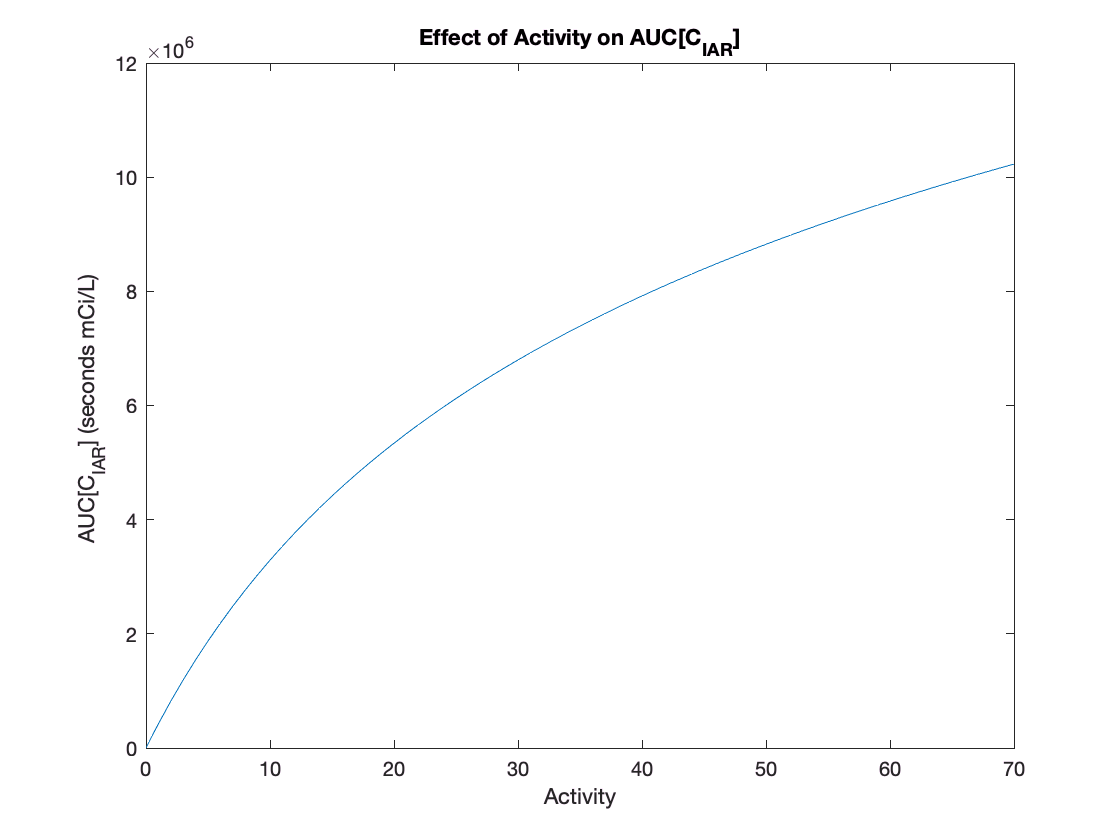

ys_adj(1,:) = ys(1,:)/ys(1,end);
ys_adj(2,:) = ys(2,:)/ys(2,end);
ys_adj(3,:) = ys(3,:)/ys(3,end);
ys_adj(4,:) = ys(4,:)/ys(4,end);

figure;
plot(activities, ys(1,:)); %plotting log(10+activities) for the x axis makes it linear
hold on;
%regression
%activities = activities/49; %convert from mCi to mg;
xlabel('Activity');
ylabel('AUC[C_{IAR}] (seconds mCi/L) ');
title('Effect of Activity on AUC[C_{IAR}]');

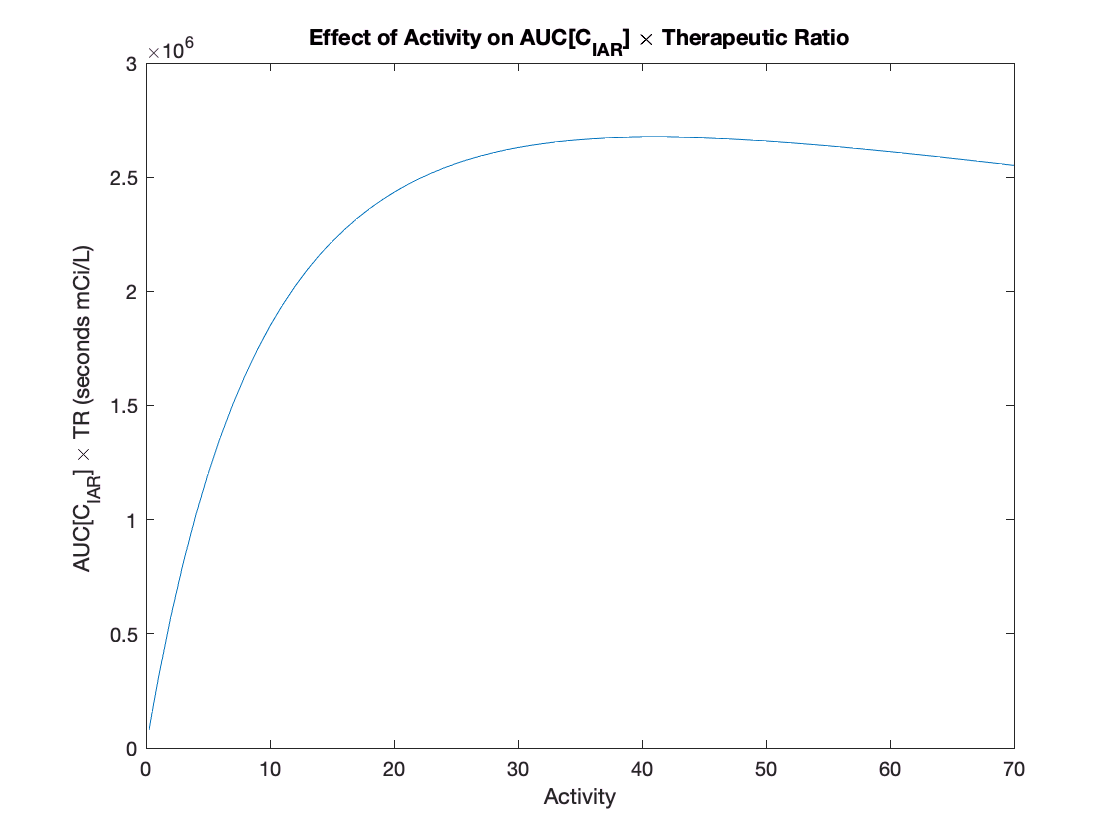


figure;
plot(activities, ys(4,:));
hold on;
%regression
%activities = activities/49; %convert from mCi to mg;
xlabel('Activity');
ylabel('AUC[C_{IAR}] \times TR (seconds mCi/L) ');
title('Effect of Activity on AUC[C_{IAR}] \times Therapeutic Ratio');

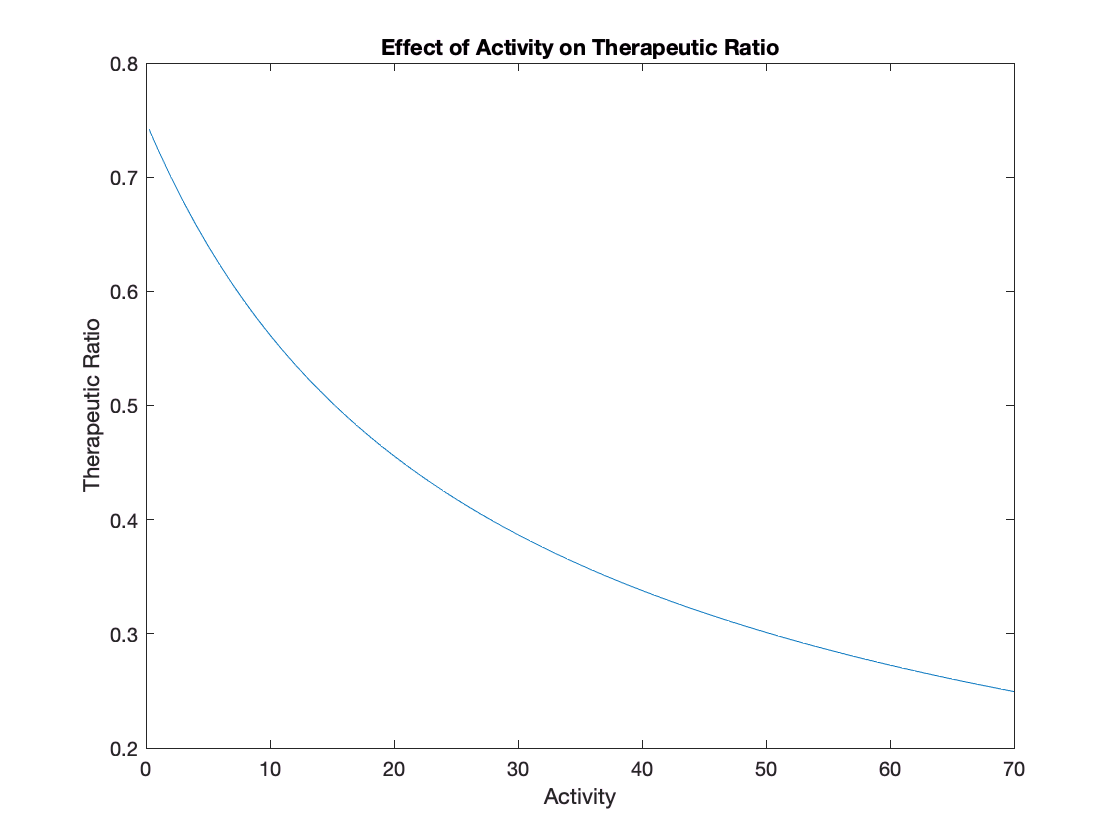


figure;
plot(activities, ys(3,:));
hold on;
%regression
%activities = activities/49; %convert from mCi to mg;
xlabel('Activity');
ylabel('Therapeutic Ratio');
title('Effect of Activity on Therapeutic Ratio');

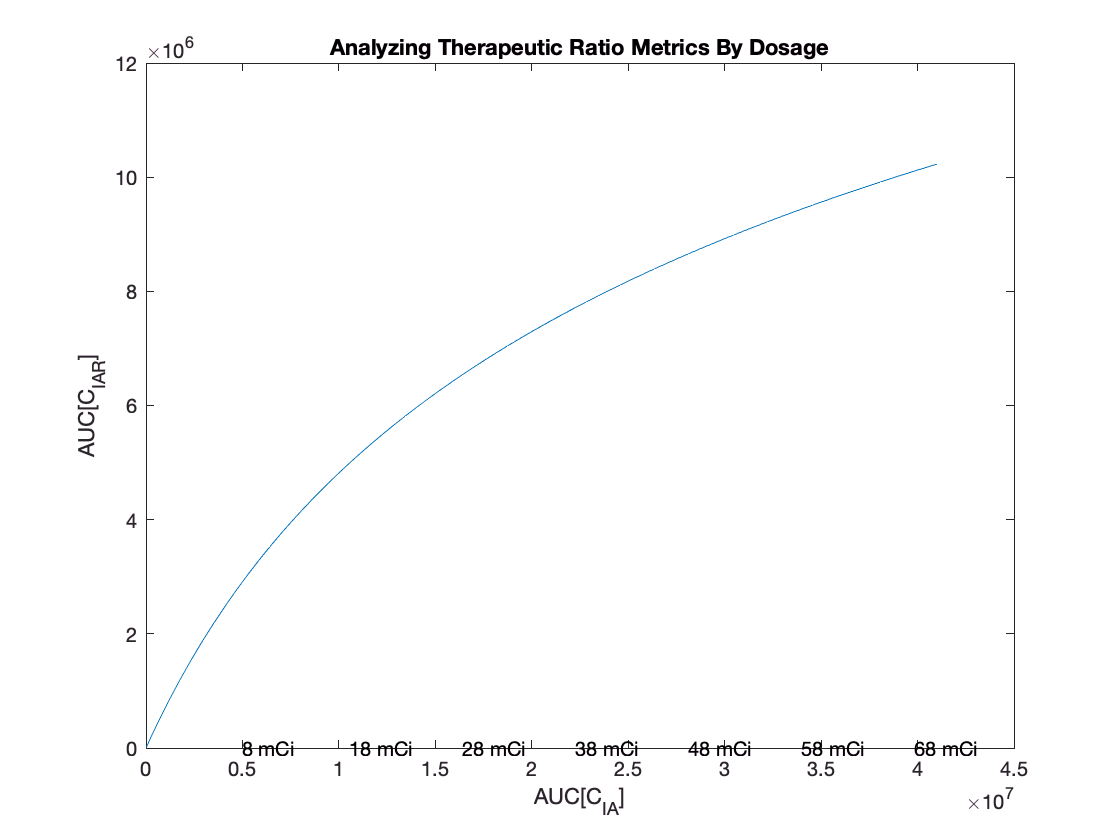


figure;
plot(ys(2,:),ys(1,:),'-');
title('Analyzing Therapeutic Ratio Metrics By Dosage');
text(ys(2,1:10:end), ys(2,1:10:end)./ys(1,1:10:end), ...
    strcat(num2str(activities(1:10:end)'),' mCi') );
xlabel('AUC[C_{IA}]');
ylabel('AUC[C_{IAR}]');

Analyze metrics simultaneously.

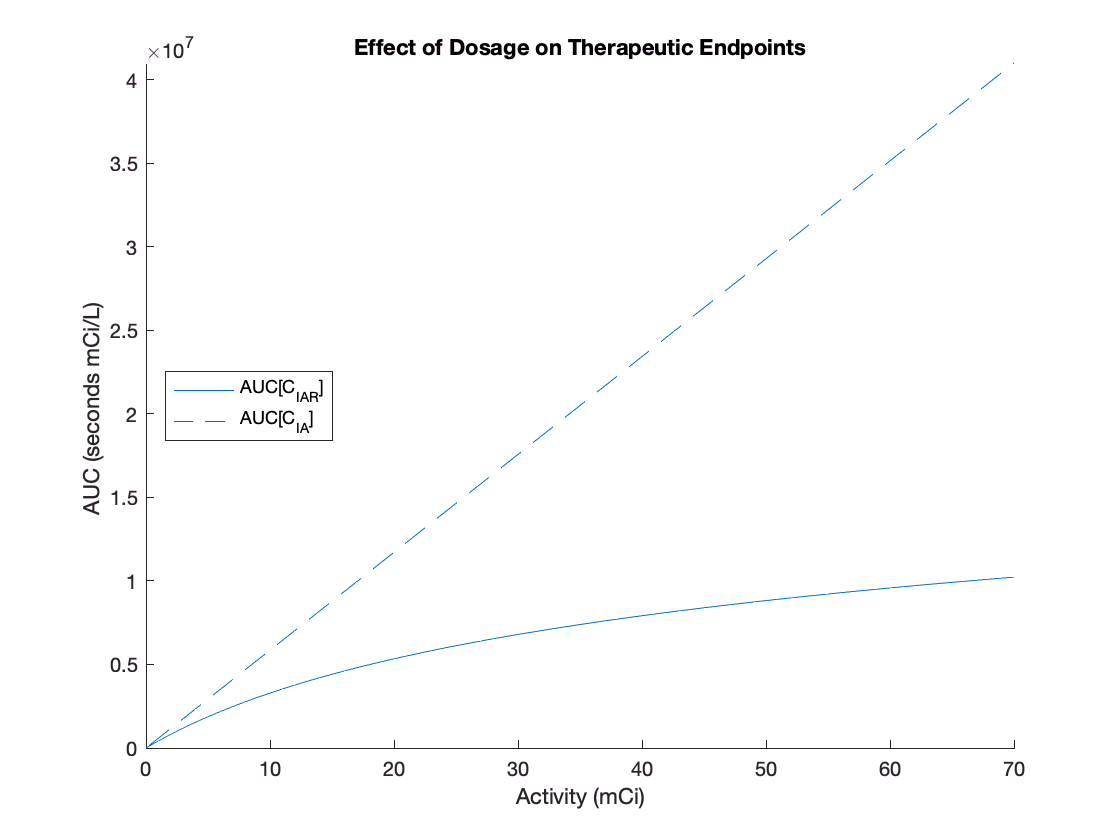

%Just AUC[C_IAR] and AUC[C_I]
figure;
hold on;
plot(activities, (ys(1,:)),'Color',[0 .447 .741] );
hold on;
plot(activities, (ys(2,:)),'--','Color',[0 .447 .741]);
ylim([0 inf]);
ylabel('AUC (seconds mCi/L) ');
title('Effect of Dosage on Therapeutic Endpoints');
legend('AUC[C_{IAR}]', 'AUC[C_{IA}]',...
    'Location','west');
xlabel('Activity (mCi)');

Therapeutic Index

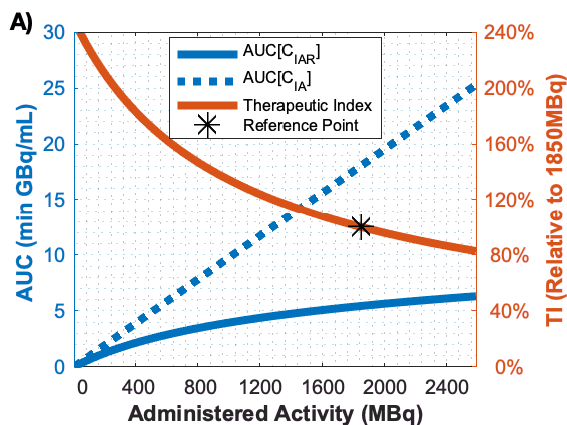

fontsize = 10; %36
axislinewidth = 1.5; %4
plotlinew = 4; %12
showtitles = false;

activitiesMBq = activities*37; %convert from mCi to MBq

I = activities==50;
currTR = ys(3,I);
currTP = ys(4,I);

figure;
hold on; box on; grid minor;

yyaxis left;
%Multiply by 37 to convert mCi to MBq. Divide by 1e6 and 60 to go from sec MBq/L to min GBq/mL.
plot(activities, (ys(1,:))*37/1e6/60,'-','LineWidth',plotlinew);
plot(activities, (ys(2,:))*37/1e6/60,':','LineWidth',plotlinew); %use : not -- so it is easier to differentiate from solid line in the legend

%sec MBq/L limits
%ylim([0 150e7]); %would be 0->4e7, but need to multiply by 37 to get MBq (then round to whole number)
%yticks([0:25:150]*1e7); %has x37 factored in
%ylabel('AUC (sec MBq/L) ','FontWeight','Bold');
%min GBq/L limits
ylim([0 30]);
ylabel('AUC (min GBq/mL) ','FontWeight','Bold');

mylylim = ylim;
mylytickct = length(get(gca,'ytick'));

yyaxis right;
plot(activities, ys(3,:),'LineWidth',plotlinew);
plot(50,currTR,'k*','MarkerSize',plotlinew*3);
ylim([0 currTR*2.4]); %empirically, we want 112 since it is divisible by 8 (number of ticks on the other side)
myrylim = ylim;
ylabel('TI (Relative to 1850MBq)','FontWeight','Bold');
%yticks([0:.25:4]*currTR);
yticks(linspace(myrylim(1),myrylim(2),mylytickct));
set(gca,'yticklabel',num2str(get(gca,'ytick')'/currTR*100,'%.0f%%'));

if showtitles
    title('Dosage Effect Curve');
end
legend({'AUC[C_{IAR}]', 'AUC[C_{IA}]','Therapeutic Index','Reference Point'},'Location','best','FontSize',8);
xlabel('Administered Activity (MBq)','FontWeight','Bold');
xlim([0 max(activities)]);

%Make the x axis appear in MBq, instead of mCi (1MBq=37mCi)
xticks([0:400:2600]/37);
set(gca,'xticklabel',num2str(get(gca,'xtick')'*37,'%.0f'));

%saveas(gcf, '+Simulations/Dosage/Dosage TR.png');
%saveas(gcf, '+Simulations/Dosage/Dosage TR.tiff');
%saveas(gcf, '+Simulations/Dosage/Dosage TR.fig');

%Add A), B), C) etc text here
letter='A';
xloc=0; yloc = 1;
if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
    %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
    annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold','tag','FigurePartLetter');
end

%set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 10 7.5]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 10 7.5]); %for showing up in the mlx file
print(['Figures/Dose/DoseWithTI'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Dose/DoseWithTI'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI

Therapeutic product

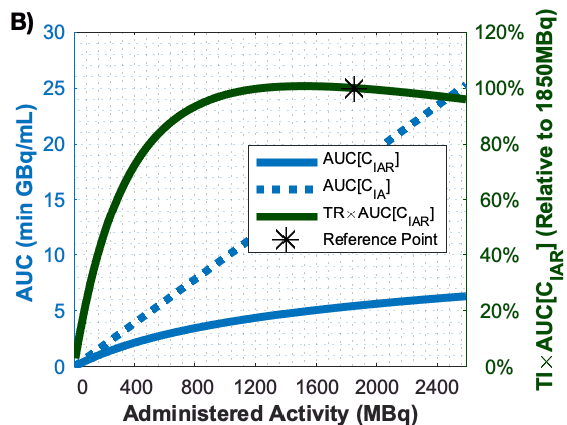

fig = figure;
%[0 .447 .741] is default blue. [0 .3 0] is dark green
set(fig, 'defaultAxesColorOrder', [0 .447 .741; 0 .3 0]);
hold on; box on; grid minor;

yyaxis left;
%Multiply by 37 to convert mCi to MBq. Divide by 1e6 and 60 to go from sec MBq/L to min GBq/mL.
plot(activities, (ys(1,:))*37/1e6/60,'LineWidth',plotlinew);
plot(activities, (ys(2,:))*37/1e6/60,':','LineWidth',plotlinew); %use : not -- so it is easier to differentiate from solid line in the legend

%sec MBq/L limits
%ylim([0 150e7]); %would be 0->4e7, but need to multiply by 37 to get MBq (then round to whole number)
%yticks([0:25:150]*1e7); %has x37 factored in
%ylabel('AUC (sec MBq/L) ','FontWeight','Bold');
%min GBq/L limits
ylim([0 30]);
ylabel('AUC (min GBq/mL) ','FontWeight','Bold');

mylylim = ylim;
mylytickct = length(get(gca,'ytick'));

yyaxis right;
plot(activities, ys(4,:),'LineWidth',plotlinew);
plot(50,currTP,'k*','MarkerSize',plotlinew*3);
ylim([0 currTP*1.2]) %empirically, we want 112 since it is divisible by 8 (number of ticks on the other side);
myrylim = ylim;
ylabel('TI\timesAUC[C_{IAR}] (Relative to 1850MBq)','FontWeight','Bold');
%yticks([0:.1:1.1]*currTP);
yticks(linspace(myrylim(1),myrylim(2),mylytickct));
set(gca,'yticklabel',num2str(get(gca,'ytick')'/currTP*100,'%.0f%%'));

if showtitles
    title('Dosage Effect Curve');
end
legend({'AUC[C_{IAR}]', 'AUC[C_{IA}]','TR\timesAUC[C_{IAR}]','Reference Point'},'Location','east','FontSize',8);
xlabel('Administered Activity (MBq)','FontWeight','Bold');
xlim([0 max(activities)]);

%Make the x axis appear in MBq, instead of mCi (1MBq=37mCi)
xticks([0:400:2600]/37);
set(gca,'xticklabel',num2str(get(gca,'xtick')'*37,'%.0f'));

%saveas(gcf, '+Simulations/Dosage/Dosage TP.png');
%saveas(gcf, '+Simulations/Dosage/Dosage TP.tiff');
%saveas(gcf, '+Simulations/Dosage/Dosage TP.fig');

%Add A), B), C) etc text here
letter='B';
xloc=0; yloc = 1;
if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
    %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
    annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold');
end

%set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 10 7.5]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 10 7.5]); %for showing up in the mlx file
print(['Figures/Dose/DoseWithTP'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Dose/DoseWithTP'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI

Find the maximum of the product, and the range of activities thar are close this max.

[mx ,I] = max(ys(4,:));
%find max of therapeutic product
prodFunc = @(ac) therapProduct(ac,...
    Vv, CL, time_values_needed,defined_params);
[maxAct, pkProd] = fminbnd( @(ac) -prodFunc(ac), 0, 70);
pkProd = -pkProd; %make fval + again, after minimizing the negative

broadCrit = 0.9*pkProd; %the range of broadness
[x1, f1] = fsolve(@(ac) prodFunc(ac)-broadCrit, 0.8*maxAct);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



[x2, f2] = fsolve(@(ac) prodFunc(ac)-broadCrit, 1.8*maxAct);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



[x1 maxAct x2]

ans =    18.9644   40.2978   89.4248


function val = therapProduct(activityAdmin,Vv, CL,...
        time_values_needed,defined_params)
    [t cIobs AUC_cIAR AUC_cIA] = solveModel(activityAdmin,...
        Vv, CL, time_values_needed,defined_params);
    val = AUC_cIAR/AUC_cIA * AUC_cIAR;
end
%AUC cI is basically linear. Prove that it isn't exactly though.
%Also find point of linearity
%{
figure;
dAUC_cI = diff(ys(2,:))'./diff(activities)';
dAUC_cIAR = diff(ys(1,:))'./diff(activities)';
[difference, I] = min(abs(dAUC_cI-dAUC_cIAR));
activities(I)
plot(activities(1:end-1)',dAUC_cI); ylim([0 inf]);
xlabel('Activity (mCi)');
ylabel('AUC cI derivative with respect to Activity');
%}